# Ejemplo de uso de matlab para el análisis cualitativo de un sistema no lineal: Péndulo Invertido.

1. Cálculo de una trayectoria en el espacio de las fases. Vamos a emplear para el calculo un función que contenga las ecuaciones de estado del sistema.,


$$
\dot x_1 = x_2\\
\dot x_2 = \frac{g}{l}\sin x_1 - \frac{b}{ml}x_2
$$


Lo vamos a hacer de modo que pueda integrarse empleando los integradores de matlab. La función se ha creado al final del código con el nombre: pendulo_inv.

Para calcular una trayectoria definimos en primer lugar un intervalo de tiempo para el cálculo, t =[t1 tf].

t = [0,15];


Además debemos dar valor a todos los parámetros,

g1 = 10; %gravedad
m1 = 10; %masa
l1 = 10; %longitud
b1 = 100; % resistencia viscosa

Por último, debemos suministrar una condición inicial,

x0 = [pi/3; 0]; %Siempre vector columna.

A continuación llamamos a ode45, un integración estándar. Ver detalles en la ayuda de matlab

 
[t,x] = ode45(@(t,x)pendulo_inv(t,x,m1,l1,g1,b1),t,x0);

Podemos ahora representar la evolución temporal de las variables de estado,

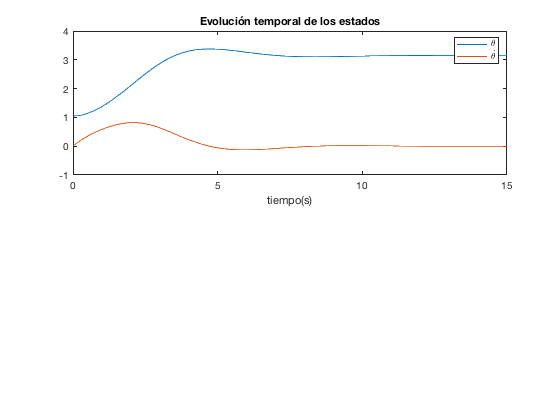

figure(1)
subplot(2,1,1)
plot(t,x)
title('Evolución temporal de los estados')
xlabel('tiempo(s)')
legend('$\theta$','$\dot{\theta}$','interpreter','latex')

Dibujamos tambien la trayectoria en el plano de fases,

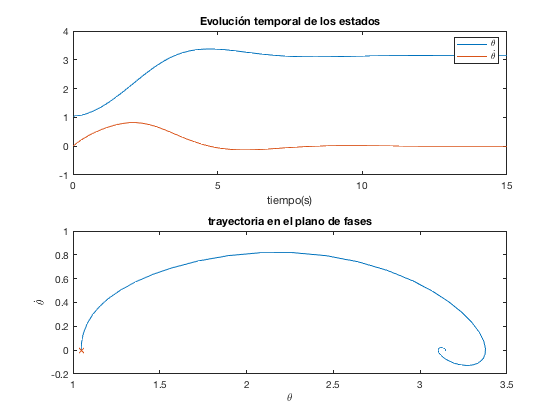

subplot(2,1,2)
plot(x(:,1),x(:,2))
hold on
plot(x0(1,1),x0(2,1),'x')
title('trayectoria en el plano de fases')
xlabel('$\theta$','interpreter','latex')
ylabel('$\dot{\theta}$','interpreter','latex')

2. Representación del campo vectorial asociado al sistema.

Para este cálculo empezamos por obtener un conjunto de puntos sobre los que obtener los valores del campo. En este caso, sabemos la posición de los puntos de equilibrio, parece interesante seleccionar una región que que contenga varios,

x1 = -3*pi/2:3*pi/18:3*pi/2;
x2 = -2:0.2:2;

Una manera rápida que construir un mallado de punto que contenga todos los pares de los puntos anteriores es usar meshgrid,

[x1m,x2m] = meshgrid(x1,x2);
xdot1m = x2m; %calculamos las componentes de campo
xdot2m = (g1*sin(x1m)-b1*x2m/m1)/l1;

Usamos el comando de matlab quiver para representar en cada punto de la malla creada en el plano de fase, el vector asociado,

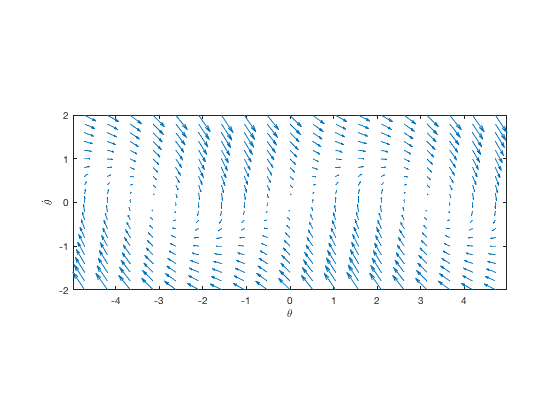

figure(2)
quiver(x1m,x2m,xdot1m,xdot2m)
axis('equal')
axis('tight')
xlabel('$\theta$','interpreter','latex')
ylabel('$\dot{\theta}$','interpreter','latex')

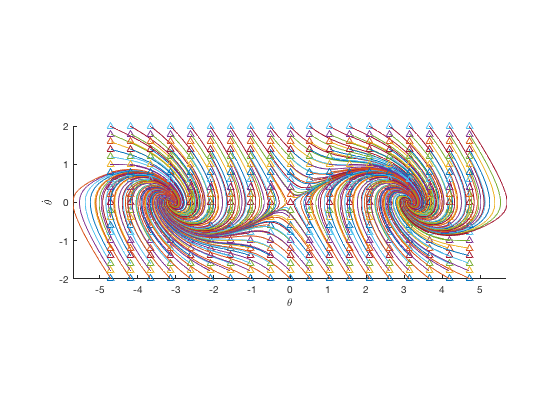


figure(3)
hold on
for i = 1:length(x1)
    for j =1: length(x2)
     [t,x] = ode45(@(t,x)pendulo_inv(t,x,m1,l1,g1,b1),t,[x1(i),x2(j)]');
     plot(x1(i),x2(j),'^')
     plot(x(:,1),x(:,2))
    end
end

axis('equal')
axis('tight')
xlabel('$\theta$','interpreter','latex')
ylabel('$\dot{\theta}$','interpreter','latex')

function xdot = pendulo_inv(t,x,m,l,g,b)
% t tiempo (s). Este sistema es autónomo, no depende del tiempo. Pero a la
% función hay que pasarle las variables en el orden t,x,parámetros para que
% poder hacerla compatible con los integradores de Matlab. Evidentemente luego no se emplea el tiempo
%para nada.

% x, vector de variables de estado, descrito como un vector columna;  
% x((1,1) angulo de pendulo con la vertical (semieje positivo) (rad);
% x(2,1) velocidad angular radianes por segundo;

% m Masa del péndulo (Kg)
% l longitud del pendulo (m)
% g Aceleración de la gravedad (m/s^2)
% b coeficiente de fricción (Kg.m/s)

%xdot vector de velocidades 
%xdot(1,1) velocidad angular (derivada temporal del ángulo)
%xdot(2,1) celeración angular (derivada temporar de la velocidad angular)

xdot(1,1) = x(2,1);
xdot(2,1) = (g*sin(x(1,1))-b*x(2,1)/m)/l;
end
